## Importing Batch Files

clc; clear;

cd 'C:\Users\Pandu\Documents\Programming\GitHub\MASK\batch1'
ds_left = imageDatastore('*_left.jpeg');
left_images = cellfun(@imread, ds_left.Files, 'UniformOutput', false);
labels = readtable('batch1.xls');
original_images = left_images;

% sgtitle('Fundus Images in Random Dataset Sample')
% hold on
% for i = 1:25
%     %     subplot(5,5,i)
%     %     imshow(left_images{i});
% end
% hold off

## Green Channel Extraction

% sgtitle('Green Channel Extraction of Fundus Images')
% hold on
% for i = 1:25
%     left_images{i} = left_images{i}(:, :, 2);
%     %     subplot(5,5,i)
%     %     imshow(left_images{i});
% end
% hold off

## CLAHE Adjustment & Median Filtration

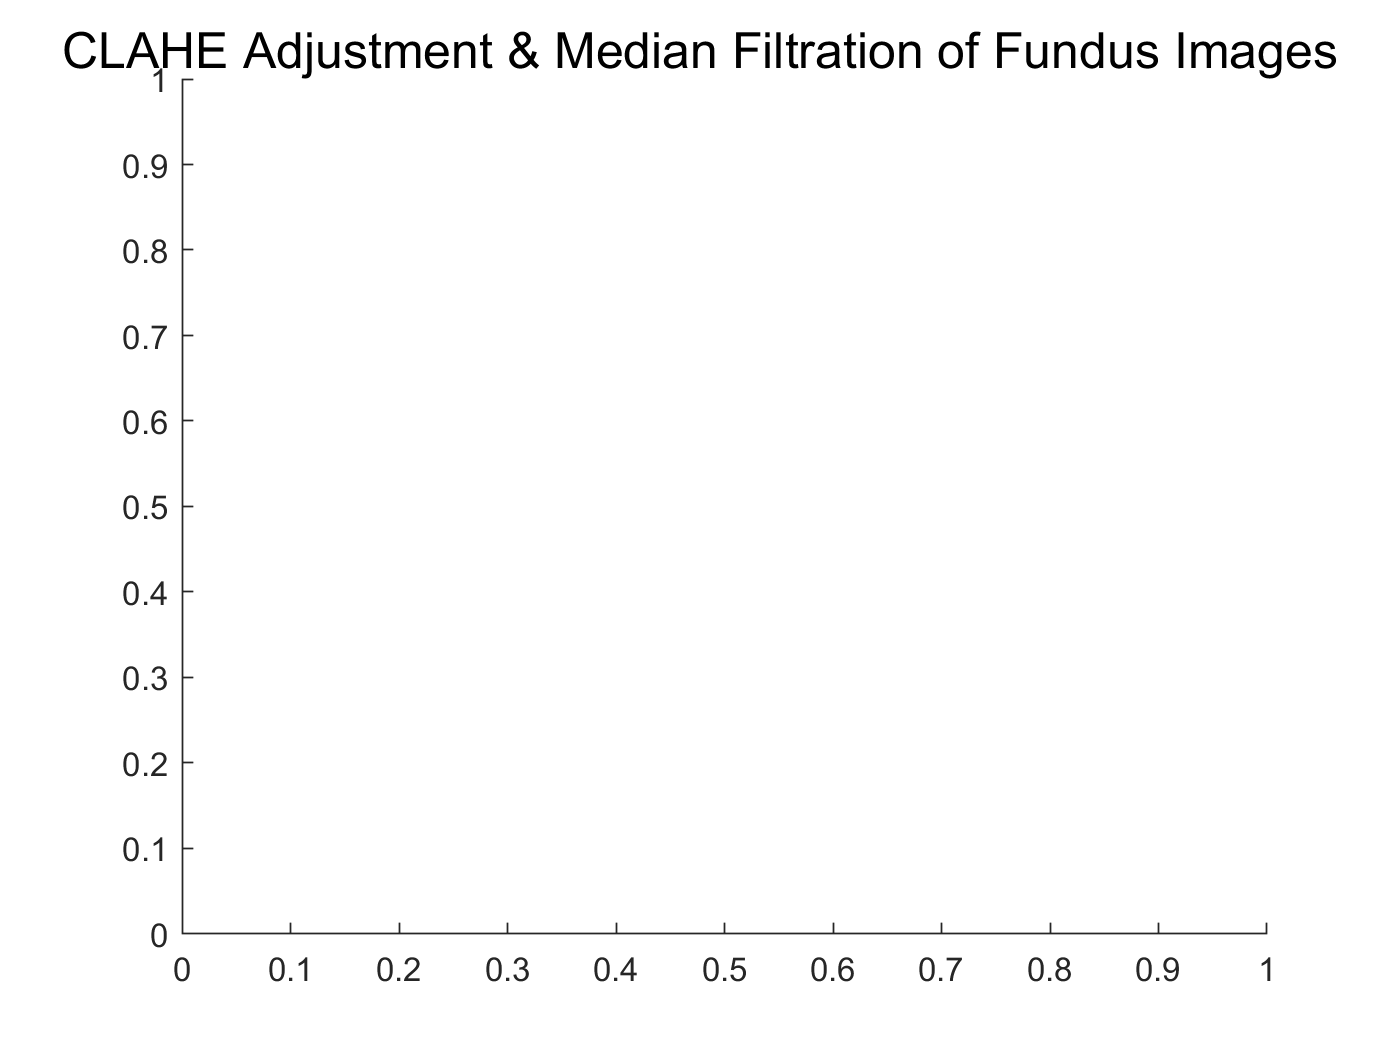

sgtitle('CLAHE Adjustment & Median Filtration of Fundus Images')
hold on
for i = 1:25
    left_images{i} = left_images{i}(:, :, 2);
    left_images{i} = adapthisteq(left_images{i});
    left_images{i} = medfilt2(left_images{i});
    %     subplot(5,5,i)
    %     imshow(left_images{i});
end
hold off

## Vessel Subtraction

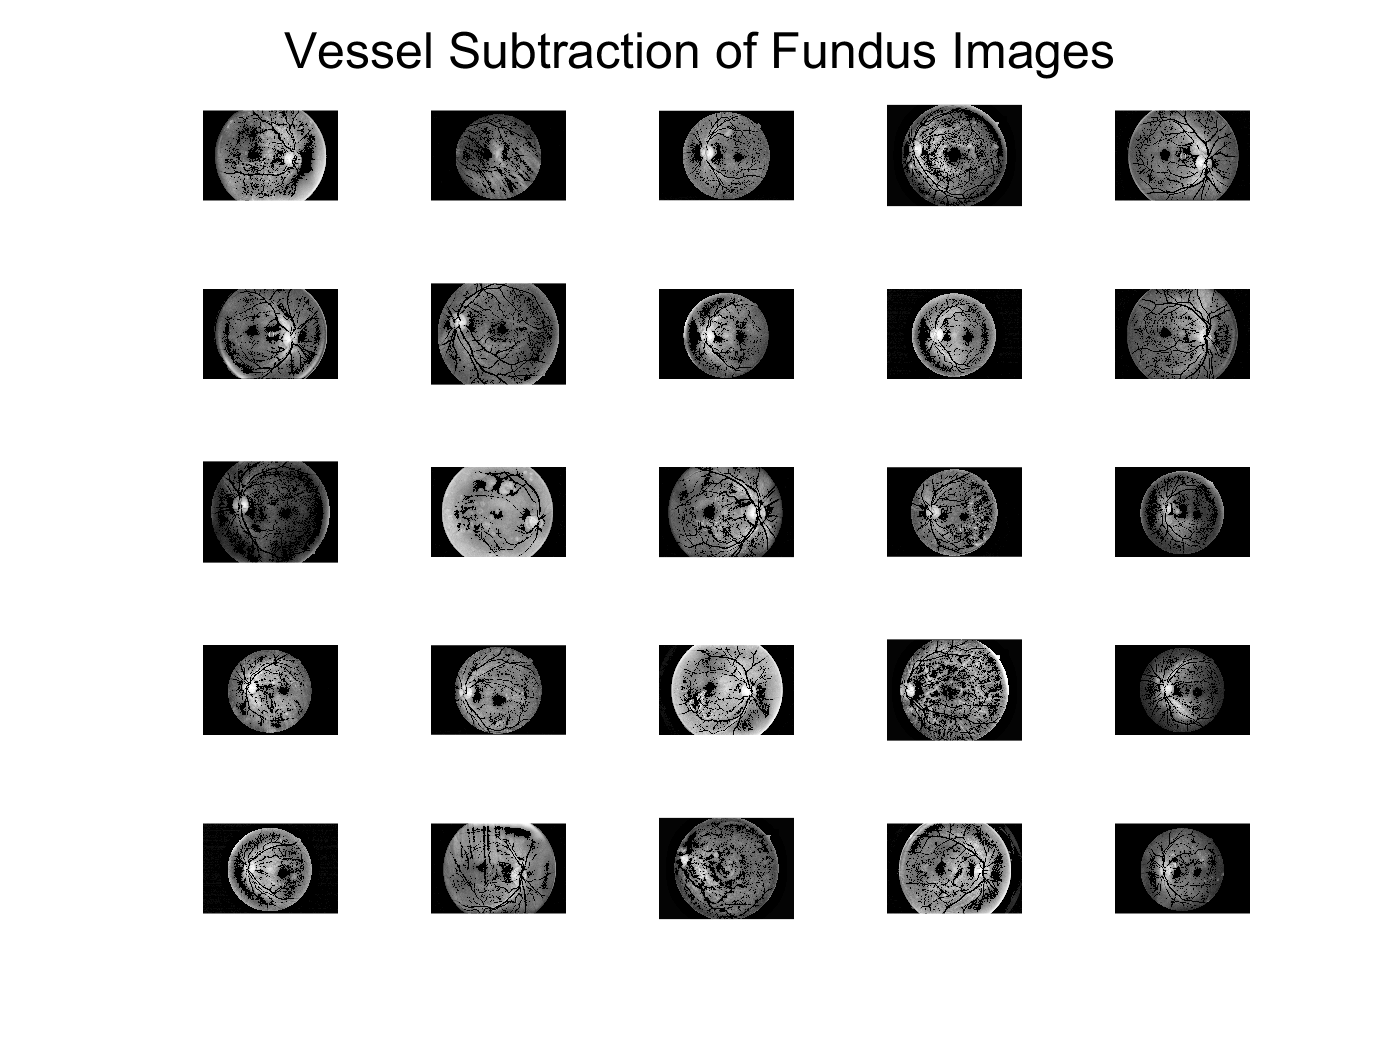

figure(1);
sgtitle('Vessel Subtraction of Fundus Images');
hold on
for i = 1:25
    se = strel('disk',100);
    vessel = imclose(left_images{i},se);
    vessel = left_images{i} - vessel;
    vessel = imadjust(left_images{i});
%     vessel = imgaussfilt(vessel);
    se = strel('line',1,90);
    se2 = strel('line',1,0);
    vessel = imdilate(vessel,[se se2]);
    se3 = strel('disk',1);
    vessel = imerode(vessel,se3);
    vessel = imbinarize(vessel, "adaptive","ForegroundPolarity","bright","Sensitivity",0.7);
    vessel_size = size(vessel,1)*size(vessel,2);
    left_images{i}(~vessel) = 0;
    subplot(5,5,i);
    imshow(left_images{i});
end

## Optic Disk Subtraction

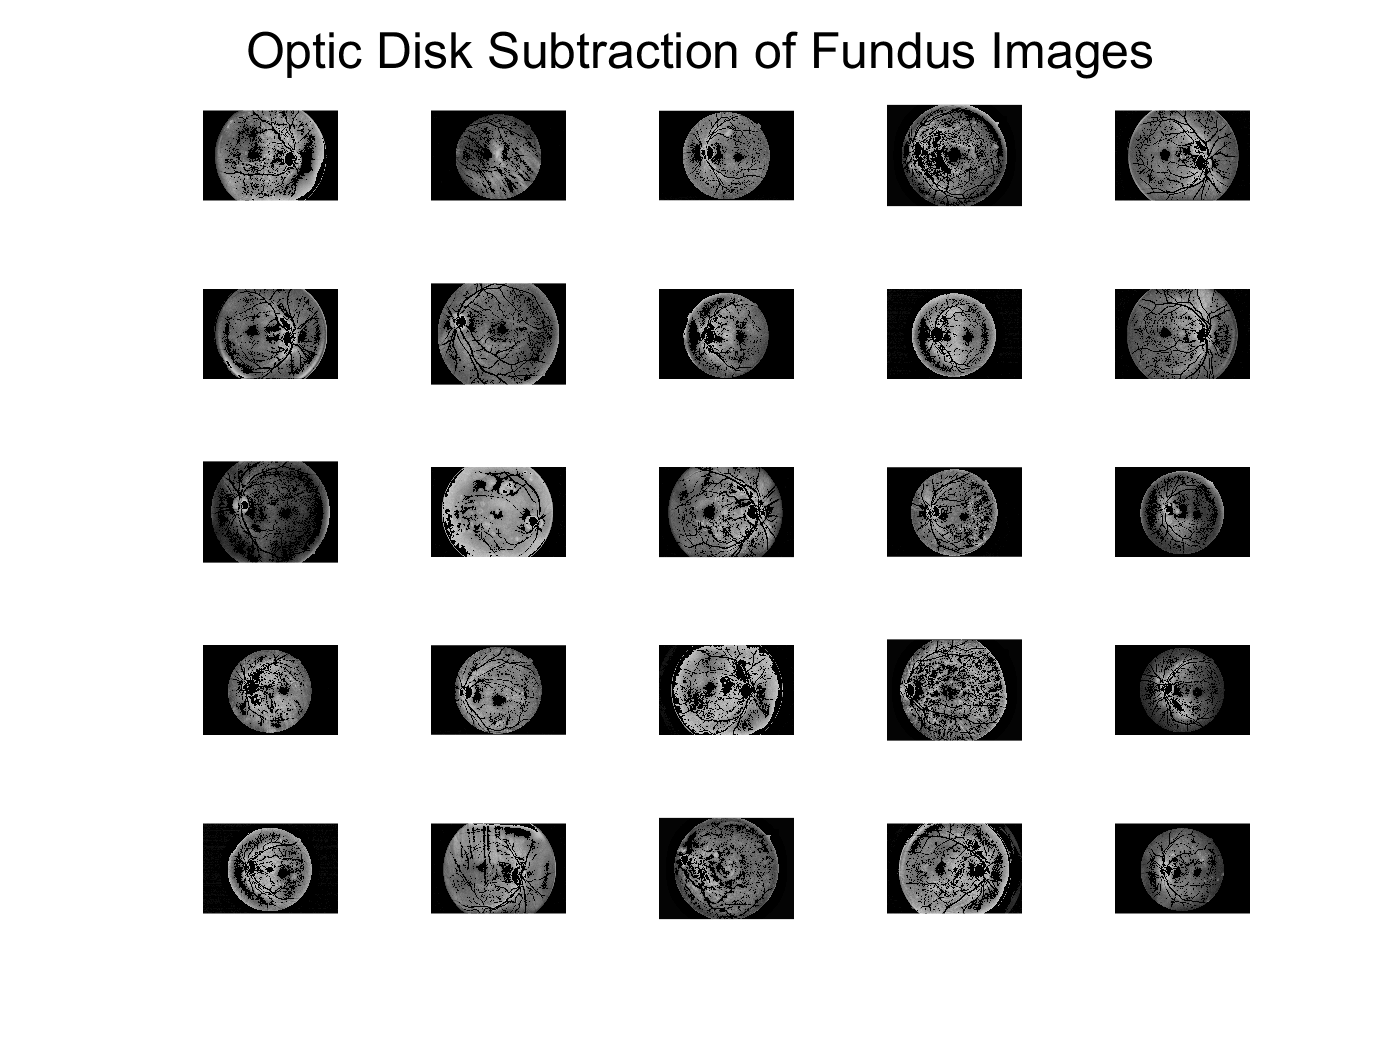

figure(2);
sgtitle('Optic Disk Subtraction of Fundus Images');
for i = 1:25
    imadjust(left_images{i});
    optic = left_images{i} > 200;
    disk = strel('disk',15);
    optic = imclose(optic, disk);
    left_images{i}(optic) = 0;    
    subplot(5,5,i);
    imshow(left_images{i});
end
hold off

hold on

for i = 1:25
    labels{i,3} = round(length(find(left_images{i} ~= 0)) / (size(left_images{i},1)*size(left_images{i},2)),3);
%     if labels{i,3} == 0.214
%         flag = 0;
%     elseif labels{i,3} == 0.232
%         flag = 1;
%     elseif labels{i,3} == 0.206
%         flag = 2;
%     elseif labels{i,3} == 0.164
%         flag = 3;
%     elseif labels{i,1} == 0.212
%         flag = 4;
%     else
%         flag = -1;
%     end
%     labels{i,4} = flag;
%     labels{i,5} = strcmp(labels{i,1},labels{i,4});
end

avgs = mean(reshape(labels{:,3},[5,5]));